clear; close all; clc

% Training set
trainFD001 = readmatrix('train_FD001.txt');
trainFD002 = readmatrix('train_FD002.txt');
trainFD003 = readmatrix('train_FD003.txt');
trainFD004 = readmatrix('train_FD004.txt');

% Test set
testFD001 = readmatrix('test_FD001.txt');
testFD002 = readmatrix('test_FD002.txt');
testFD003 = readmatrix('test_FD003.txt');
testFD004 = readmatrix('test_FD004.txt');

% RUL (Remaining Useful Life)
RUL_FD001 = readmatrix('RUL_FD001.txt');
RUL_FD002 = readmatrix('RUL_FD002.txt');
RUL_FD003 = readmatrix('RUL_FD003.txt');
RUL_FD004 = readmatrix('RUL_FD004.txt');


% Dataset
trainSets = {trainFD001, trainFD002, trainFD003, trainFD004};
testSets  = {testFD001,  testFD002,  testFD003,  testFD004};
RULsets   = {RUL_FD001, RUL_FD002, RUL_FD003, RUL_FD004};
dataset_names = {'FD001','FD002','FD003','FD004'};

% Functions helper 
function T2 = t2comp(data, loadings, latent)
    k = size(loadings,2);
    scores = data*loadings;
    latent_rep = repmat(sqrt(latent(1:k))', size(scores,1),1);
    standscores = scores ./ latent_rep;
    T2 = sum(standscores.^2,2);
end

function Q = qcomp(data, loadings)
    k = size(loadings,2);
    scores = data*loadings;
    reconstructed = scores*loadings';
    residuals = data - reconstructed;
    Q = sum(residuals.^2,2);
end

function T2_contrib = t2contr(x_row, loadings, latent, k)
    score_row = x_row*loadings;
    T2_contrib = abs( (score_row ./ sqrt(latent(1:k))') ) * abs(loadings');
end

function Q_contrib = qcontr(x_row, loadings, k)
    reconstructed_row = (x_row*loadings)*loadings';
    residuals_row = x_row - reconstructed_row;
    Q_contrib = residuals_row.^2;
end


==================== Dataset: FD001 ====================



--- Alpha = 95.0% ---


Alpha = 95.0% | TPR = 19.0% | FAR = 80.0% | Mean Lead Time  = 103.21 cycles


Most frequent top sensors for T² (Alpha 95.0%): Sensor8, Sensor2, Sensor1


Most frequent top sensors for Q  (Alpha 95.0%): Sensor14, Sensor13, Sensor9




--- Alpha = 99.0% ---


Alpha = 99.0% | TPR = 25.0% | FAR = 56.0% | Mean Lead Time  = 91.16 cycles


Most frequent top sensors for T² (Alpha 99.0%): Sensor8, Sensor2, Sensor20


Most frequent top sensors for Q  (Alpha 99.0%): Sensor10, Sensor14, Sensor9




--- Alpha = 99.5% ---


Alpha = 99.5% | TPR = 24.0% | FAR = 43.0% | Mean Lead Time  = 78.45 cycles


Most frequent top sensors for T² (Alpha 99.5%): Sensor8, Sensor20, Sensor2


Most frequent top sensors for Q  (Alpha 99.5%): Sensor6, Sensor13, Sensor10



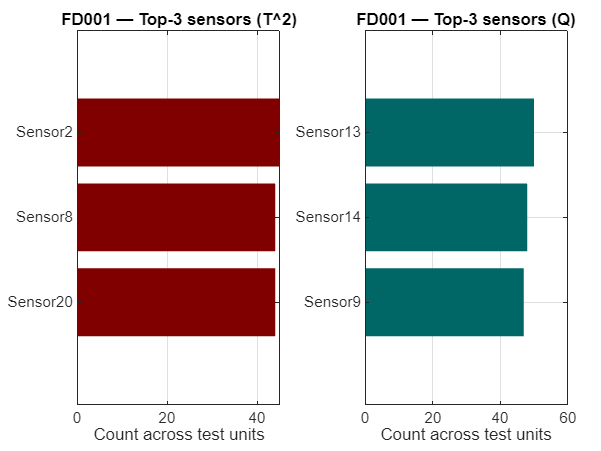


==================== Dataset: FD002 ====================



--- Alpha = 95.0% ---


Alpha = 95.0% | TPR = 22.0% | FAR = 69.9% | Mean Lead Time  = 110.11 cycles


Most frequent top sensors for T² (Alpha 95.0%): Sensor3, Sensor16, Sensor22


Most frequent top sensors for Q  (Alpha 95.0%): Sensor17, Sensor14, Sensor7




--- Alpha = 99.0% ---


Alpha = 99.0% | TPR = 24.3% | FAR = 35.5% | Mean Lead Time  = 87.28 cycles


Most frequent top sensors for T² (Alpha 99.0%): Sensor3, Sensor16, Sensor22


Most frequent top sensors for Q  (Alpha 99.0%): Sensor17, Sensor19, Sensor2




--- Alpha = 99.5% ---


Alpha = 99.5% | TPR = 24.3% | FAR = 29.3% | Mean Lead Time  = 78.54 cycles


Most frequent top sensors for T² (Alpha 99.5%): Sensor3, Sensor16, Sensor22


Most frequent top sensors for Q  (Alpha 99.5%): Sensor19, Sensor2, Sensor13



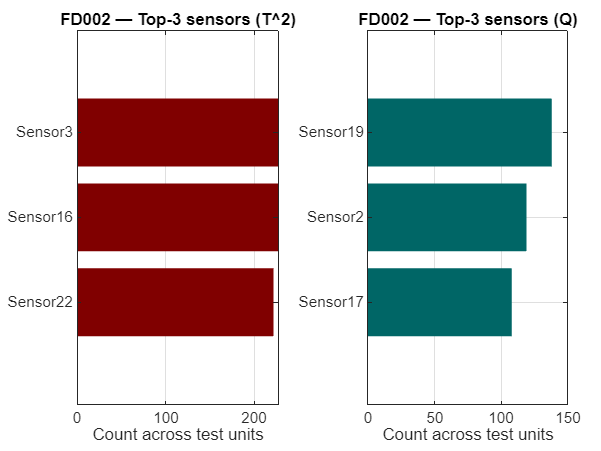


==================== Dataset: FD003 ====================



--- Alpha = 95.0% ---


Alpha = 95.0% | TPR = 23.0% | FAR = 76.0% | Mean Lead Time  = 121.10 cycles


Most frequent top sensors for T² (Alpha 95.0%): Sensor4, Sensor19, Sensor5


Most frequent top sensors for Q  (Alpha 95.0%): Sensor21, Sensor17, Sensor20




--- Alpha = 99.0% ---


Alpha = 99.0% | TPR = 35.0% | FAR = 38.0% | Mean Lead Time  = 84.04 cycles


Most frequent top sensors for T² (Alpha 99.0%): Sensor4, Sensor12, Sensor2


Most frequent top sensors for Q  (Alpha 99.0%): Sensor21, Sensor8, Sensor20




--- Alpha = 99.5% ---


Alpha = 99.5% | TPR = 32.0% | FAR = 30.0% | Mean Lead Time  = 88.10 cycles


Most frequent top sensors for T² (Alpha 99.5%): Sensor2, Sensor1, Sensor12


Most frequent top sensors for Q  (Alpha 99.5%): Sensor21, Sensor8, Sensor20



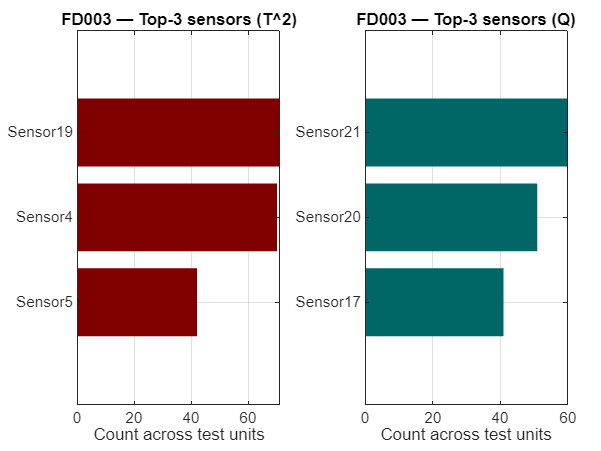


==================== Dataset: FD004 ====================



--- Alpha = 95.0% ---


Alpha = 95.0% | TPR = 16.1% | FAR = 64.5% | Mean Lead Time  = 140.21 cycles


Most frequent top sensors for T² (Alpha 95.0%): Sensor3, Sensor16, Sensor22


Most frequent top sensors for Q  (Alpha 95.0%): Sensor17, Sensor14, Sensor13




--- Alpha = 99.0% ---


Alpha = 99.0% | TPR = 16.9% | FAR = 31.9% | Mean Lead Time  = 112.41 cycles


Most frequent top sensors for T² (Alpha 99.0%): Sensor3, Sensor16, Sensor22


Most frequent top sensors for Q  (Alpha 99.0%): Sensor19, Sensor13, Sensor2




--- Alpha = 99.5% ---


Alpha = 99.5% | TPR = 16.1% | FAR = 23.8% | Mean Lead Time  = 101.48 cycles


Most frequent top sensors for T² (Alpha 99.5%): Sensor3, Sensor16, Sensor22


Most frequent top sensors for Q  (Alpha 99.5%): Sensor13, Sensor19, Sensor2



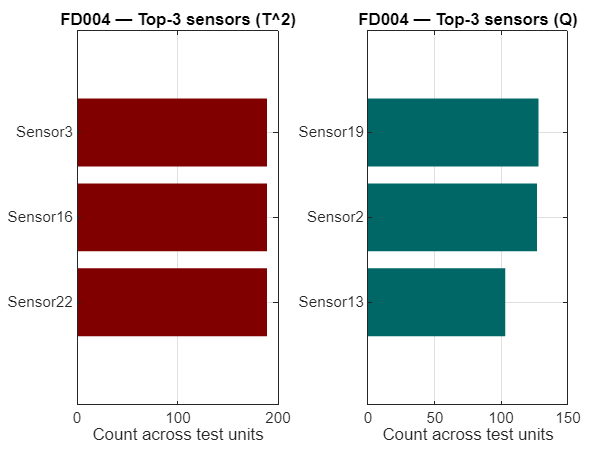

lead_window = 50;  
alpha_levels = [0.95, 0.99, 0.995]; 
trainSets = {trainFD001, trainFD002, trainFD003, trainFD004};
testSets  = {testFD001,  testFD002,  testFD003,  testFD004};
dataset_names = {'FD001','FD002','FD003','FD004'};

for f = 1:4
    fprintf('\n==================== Dataset: %s ====================\n', dataset_names{f});
    trainData = trainSets{f};
    testData  = testSets{f};
    unit_train  = trainData(:,1);
    cycle_train = trainData(:,2);
    X_train     = trainData(:,3:end);
    X_test_all  = testData(:,3:end);
    test_units  = unique(testData(:,1));
    total_engines = numel(test_units);

    constVars = find(var(X_train)==0);
    if ~isempty(constVars)
        X_train(:,constVars) = [];
        X_test_all(:,constVars) = [];
    end
    nVar = size(X_train,2);
    varNames = arrayfun(@(x) sprintf('Sensor%d',x), 1:nVar, 'UniformOutput', false);

    % Healthy Data (first 30% of cycles for each engine)
    uniqueUnits = unique(unit_train);
    healthy_data_indices = [];
    for i = 1:numel(uniqueUnits)
        unit_id = uniqueUnits(i);
        idx = find(unit_train==unit_id);
        max_cycle = max(cycle_train(idx));
        healthy_data_indices = [healthy_data_indices; idx(cycle_train(idx) <= floor(0.3*max_cycle))];
    end
    X_healthy = X_train(healthy_data_indices,:);

    % PCA
    mu = mean(X_healthy);
    sig = std(X_healthy);
    Xh_scaled = (X_healthy - mu)./sig;
    [coeff,~,latent,~,explained] = pca(Xh_scaled,'Centered',false);
    cumExplained = cumsum(explained);
    k = find(cumExplained>=90,1); if isempty(k), k=size(coeff,2); end
    coeff_k = coeff(:,1:k);
    latent_k = latent(1:k);

    T2_h = t2comp(Xh_scaled, coeff_k, latent_k);
    Q_h  = qcomp(Xh_scaled, coeff_k);

    for a = 1:numel(alpha_levels)
        alpha = alpha_levels(a);
        alarm_T2 = prctile(T2_h, alpha*100);
        alarm_Q  = prctile(Q_h, alpha*100);

        TP = 0; FP = 0; leadtimes = [];

        fprintf('\n--- Alpha = %.1f%% ---\n', alpha*100);

        freq_T2 = zeros(1,nVar);
        freq_Q  = zeros(1,nVar);

        for u = 1:total_engines
            idx_test = find(testData(:,1) == test_units(u));
            X_test = X_test_all(idx_test,:);
            N_test = size(X_test,1);
            X_scaled = (X_test - mu) ./ sig;
            T2_test = t2comp(X_scaled, coeff_k, latent_k);
            Q_test  = qcomp(X_scaled, coeff_k);

            % First alarm
            alarm_idx_T2 = find(T2_test > alarm_T2,1);
            alarm_idx_Q  = find(Q_test > alarm_Q,1);
            if ~isempty(alarm_idx_T2)
                first_alarm = alarm_idx_T2;
            elseif ~isempty(alarm_idx_Q)
                first_alarm = alarm_idx_Q;
            else
                first_alarm = NaN;
            end

            % Lead time and classification
            if ~isnan(first_alarm)
                leadtime = N_test - first_alarm;
                leadtimes(end+1) = leadtime;
                if leadtime <= lead_window
                    TP = TP + 1;
                else
                    FP = FP + 1;
                end

                % Top 3 sensors 
                xrow = X_scaled(first_alarm,:);
                T2_contrib = t2contr(xrow, coeff_k, latent_k, k);
                Q_contrib  = qcontr(xrow, coeff_k, k);

                [~, idxT2] = sort(T2_contrib, 'descend');
                [~, idxQ]  = sort(Q_contrib,  'descend');
                topN = 3; 

                %fprintf('Engine %d | Lead Time: %d cycles\n', test_units(u), leadtime);
                %fprintf('  Top %d sensors T²: %s, %s, %s\n', topN, ...
                %   varNames{idxT2(1)}, varNames{idxT2(2)}, varNames{idxT2(3)});
                %fprintf('  Top %d sensors Q : %s, %s, %s\n\n', topN, ...
                %   varNames{idxQ(1)}, varNames{idxQ(2)}, varNames{idxQ(3)});

                freq_T2(idxT2(1:topN)) = freq_T2(idxT2(1:topN)) + 1;
                freq_Q(idxQ(1:topN))   = freq_Q(idxQ(1:topN)) + 1;
            end
        end

        % Global metrics
        TPR = 100*TP/total_engines;
        FAR = 100*FP/total_engines;
        mean_LT = mean(leadtimes,'omitnan');

        fprintf('Alpha = %.1f%% | TPR = %.1f%% | FAR = %.1f%% | Mean Lead Time  = %.2f cycles\n', ...
            alpha*100, TPR, FAR, mean_LT);

        [~, sorted_T2] = sort(freq_T2,'descend');
        [~, sorted_Q]  = sort(freq_Q,'descend');
        fprintf('Most frequent top sensors for T² (Alpha %.1f%%): %s, %s, %s\n', ...
            alpha*100, varNames{sorted_T2(1)}, varNames{sorted_T2(2)}, varNames{sorted_T2(3)});
        fprintf('Most frequent top sensors for Q  (Alpha %.1f%%): %s, %s, %s\n\n', ...
            alpha*100, varNames{sorted_Q(1)}, varNames{sorted_Q(2)}, varNames{sorted_Q(3)});
    end

    % results for alpha=0.95
    alpha = alpha_levels(1);
    
    alarm_T2 = prctile(T2_h, alpha*100);
    alarm_Q  = prctile(Q_h,  alpha*100);
    
    freq_T2 = zeros(1,nVar);
    freq_Q  = zeros(1,nVar);
    
    for u = 1:total_engines
        idx_test = find(testData(:,1) == test_units(u));
        X_test   = X_test_all(idx_test,:);
        N_test   = size(X_test,1);
    
        X_scaled = (X_test - mu) ./ sig;
 
        T2_test = t2comp(X_scaled, coeff_k, latent_k);
        Q_test  = qcomp(X_scaled,  coeff_k);
    
        % First alarm (T^2 OR Q)
        viol = (T2_test > alarm_T2) | (Q_test > alarm_Q);
        first_alarm = find(viol, 1, 'first');
        if isempty(first_alarm), continue; end
    
        % Contribution
        xrow        = X_scaled(first_alarm,:);
        T2_contrib  = t2contr(xrow, coeff_k, latent_k, k);
        Q_contrib   = qcontr(xrow,  coeff_k, k);
   
        [~, idxT2] = sort(T2_contrib, 'descend');
        [~, idxQ ] = sort(Q_contrib,  'descend');
        topN = min(3, nVar);
        freq_T2(idxT2(1:topN)) = freq_T2(idxT2(1:topN)) + 1;
        freq_Q(idxQ(1:topN))   = freq_Q(idxQ(1:topN))   + 1;
    end
    
    % Find TOP-3 for T^2 and for Q 
    topN = min(3, nVar);
    [valsT2, indsT2] = maxk(freq_T2, topN);
    [valsQ,  indsQ ] = maxk(freq_Q,  topN);
    
    namesT2 = varNames(indsT2);
    namesQ  = varNames(indsQ);
    
    figure('Color','w','Name',sprintf('%s — Top-3 sensors', dataset_names{f}));
    tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
    
    % Subplot T^2
    nexttile; 
    barh(flip(valsT2),'FaceColor',[0.50 0.00 0.00],'EdgeColor','none'); grid on; box on;
    yticks(1:topN);
    yticklabels(flip(namesT2));
    xlabel('Count across test units');
    title(sprintf('%s — Top-3 sensors (T^2)', dataset_names{f}), 'Interpreter','none');
    
    % Subplot Q
    nexttile; 
    barh(flip(valsQ),'FaceColor',[0.00 0.40 0.40],'EdgeColor','none'); grid on; box on;
    yticks(1:topN); 
    yticklabels(flip(namesQ));
    xlabel('Count across test units');
    title(sprintf('%s — Top-3 sensors (Q)', dataset_names{f}), 'Interpreter','none');
end